# **Embedded Coder Support Package for Texas Instruments AM13x**

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))

## Build Configuration

By Default, we are using **TI ARM Clang Compiler AM13x | gmake** toolchain. You can choose **IAR ARM Compiler AM13x | gmake** toolchain optionally.

We have 4 build configurations, Faster Builds, Faster Runs, Debug and Specify. Faster Builds and Faster Runs use release libraries of the sdk, while Debug uses the debug libraries. In Specify, you can define custom flags. 

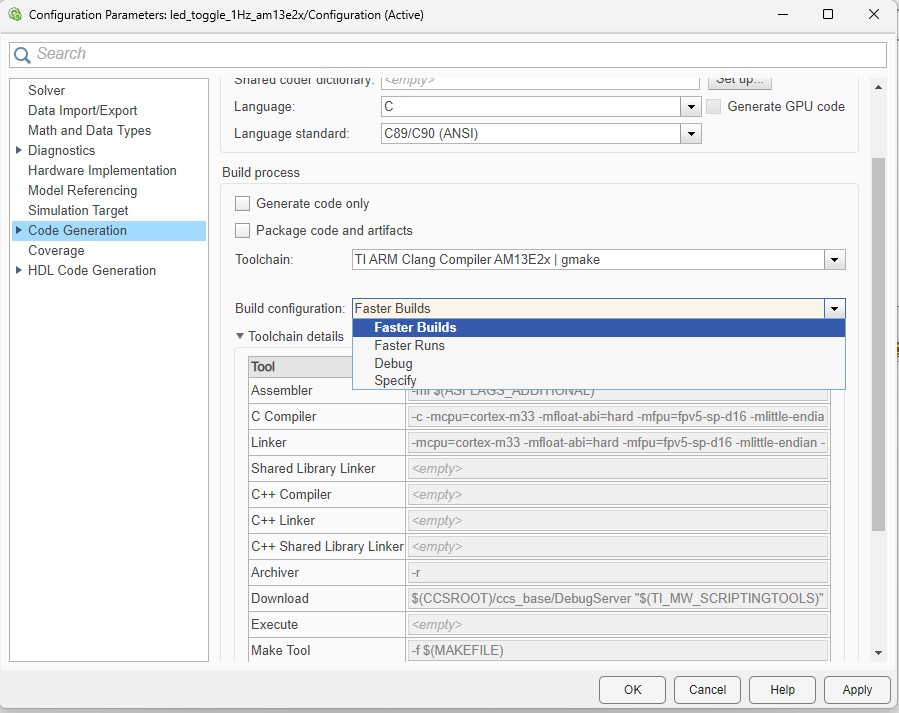

## System Configuration Tool (SysConfig)

### Introduction

SysConfig is a configuration tool designed to simplify hardware and software configuration challenges to accelerate software development. SysConfig provides an intuitive graphical user interface for configuring pins, peripherals, clock tree and other components. SysConfig will automatically detect, expose and resolve conflicts to speed software development.

### Features

The features available vary by the device and software development kit used.

- Pin mux

- Peripheral/driver configuration

- Clock tree configuration

- Memory configuration

- Automatic code generation for peripheral initialization

- Device- and board-level views

- Contextual documentation

- Real-time code preview

### SysConfig integration with HSP

### Overview

Every Simulink model you create requires a corresponding SysConfig file (`.syscfg`) to be linked to it. The SysConfig file is used to easily configure and generate the hardware initialization code for your AM13x microcontroller.Configuring SysConfig in Your Model Accessing SysConfig Settings

To configure the SysConfig file for your Simulink model:

- Open your Simulink model (`.slx` file)

- Navigate to: Hardware Settings → Hardware Implementation → Target Hardware Resources → SysConfig → SysConfig Project File

Available Options

The SysConfig configuration panel provides three key options:

- Create: Generate a new SysConfig file for your project

- Browse: Select an existing SysConfig file to link with your model

- Launch: Open the linked SysConfig file in the SysConfig GUI for editing

### Setting Up a New Project

When you first create a Simulink model, a default syscfg file will be loaded. To customize the initialization, you can:

- Create a SysConfig file using the "Create" button or manually

- Link the SysConfig file to your Simulink model using the "Browse" button or by entering the path

- Configure your hardware in the SysConfig GUI (accessible via "Launch" button or by directly opening the .syscfg file)

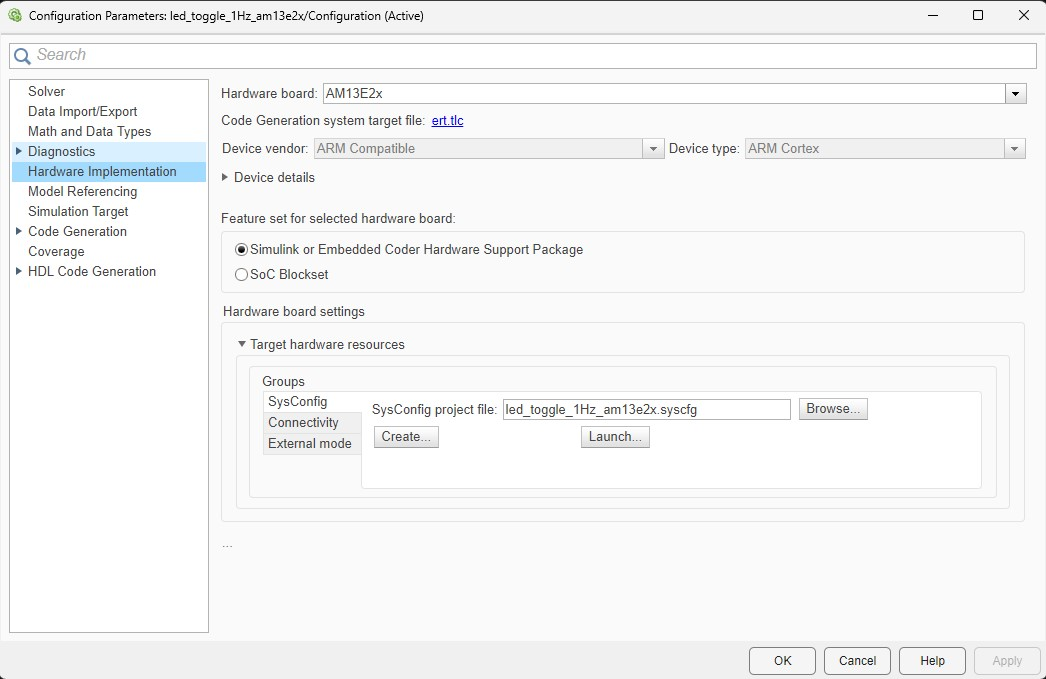

### Path Configuration: Absolute vs. Relative

Absolute Paths

When you use the Browse button to select a SysConfig file, the HSP stores the complete file path (e.g., `C:\Projects\MyProject\led_toggle_1Hz_am13x.syscfg`). This works well for fixed project locations.

Relative Paths (Recommended)

You can also use relative paths for better portability. Relative paths are specified relative to the location of your `.slx` file.

Example:

- Model file: `C:\Projects\MyProject\led_toggle_1Hz_am13x.slx`

- SysConfig file: `C:\Projects\MyProject\led_toggle_1Hz_am13x.syscfg`

- Relative path: `led_toggle_1Hz_am13x.syscfg`

Best Practice: Co-located Files

We recommend keeping your `.slx` and `.syscfg` files in the same folder with matching names. This approach:

- Simplifies path management: Use just the filename as a relative path

- Improves portability: Projects work regardless of installation location

- Follows industry standards: Easy for team collaboration and version control

All HSP example projects follow this convention. For instance, the `led_toggle_1Hz_am13x` example contains:

led_toggle_1Hz_am13x.slx
led_toggle_1Hz_am13x.syscfg

The SysConfig path is simply set to: `led_toggle_1Hz_am13x.syscfg`Build Process IntegrationCode Generation

During the build process, the HSP automatically:

- Reads your SysConfig file (`.syscfg`)

- Generates initialization code in the build folder (`{model_name}_ert_rtw/`)

- Creates configuration files: `ti_sdk_dl_config.c` and `ti_sdk_dl_config.h`

- Includes the generated code in your project via `am13x_main.h`

These generated files contain all the hardware initialization code based on your SysConfig settings, including:

- Clock configuration

- GPIO setup

- Peripheral initialization

- Interrupt configuration

Build Folder Structure

After building, you'll find the generated files under *_ert codegen folder:

ti_sdk_dl_config.c
ti_sdk_dl_config.h

This integration ensures that your hardware is properly configured before your Simulink-generated code executes, providing a seamless development experience.

## Connectivity

MATLAB/Simulink communicates with AM13x using Serial interface for some of the key MBD features such as PIL and External Mode.

Set up appropriate serial port and baud rate as shown in the below image.

Configured serial port and baud rate are saved as MATLAB preferences to be used across AM13x models. 

#### Troubleshooting Connectivity Issues:  

Sometimes Connectivity settings and MATLAB preferences lose synchronization, reopen the model settings and set it up again.

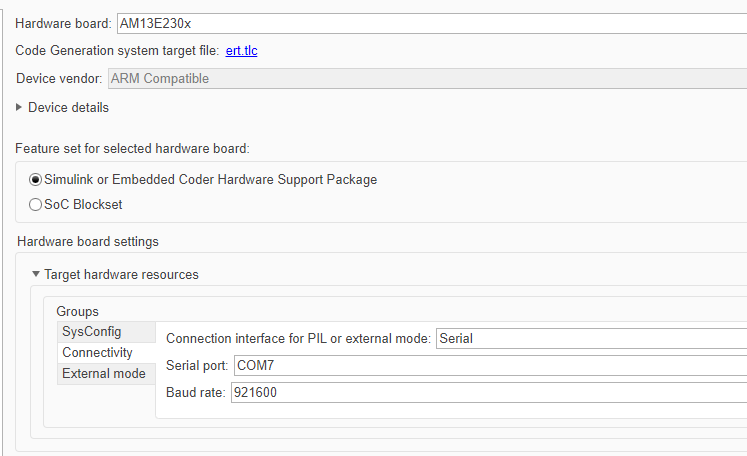

[Back to main page](matlab:open('../chapter_1_introduction/introduction_am13x.mlx'))